% Wykres 1: zmienny SCS i min P_switch
% Parametry stałe
T_total = 2500;
scs = [15, 30, 60, 120];
SSSG0_frequency = 1;
SSSG1_frequency = 8;
P_switch = [25, 25, 25, 40];
searchSpaceSwitchTimer = 80;
packet_frequency = [100, 250, 500, 5000];
packet_data_duration = 20;
dci_latency = 6;

% Inicjalizacja wyników
energy_gains_1 = zeros(length(scs), length(packet_frequency));
mean_delays_1 = zeros(length(scs), length(packet_frequency));

% Symulacja dla każdego SCS i każdej częstotliwości pakietów
for scs_idx = 1:length(scs)
    
    for freq_idx = 1:length(packet_frequency)
        
        [energy_gains_1(scs_idx, freq_idx), mean_delays_1(scs_idx, freq_idx)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs(scs_idx), SSSG0_frequency, SSSG1_frequency, ...
                P_switch(scs_idx), searchSpaceSwitchTimer, packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 2500 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 250.64
Time 0.00 ms | SSSG0 monitoring | Counter: 5 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 4 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 3 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no switch)
Time 3.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 400.00 mJ (switching) / 400.00 mJ (no switch)
Time 4.00 ms | SSSG0 monitoring | Counter: 1 | Energy used: 500.00 mJ (switching) / 500.00 mJ (no switch)
Time 5.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 600.00 mJ (switching) / 600.00 mJ (no switch)
Time 6.00 ms | SSSG0 monitor

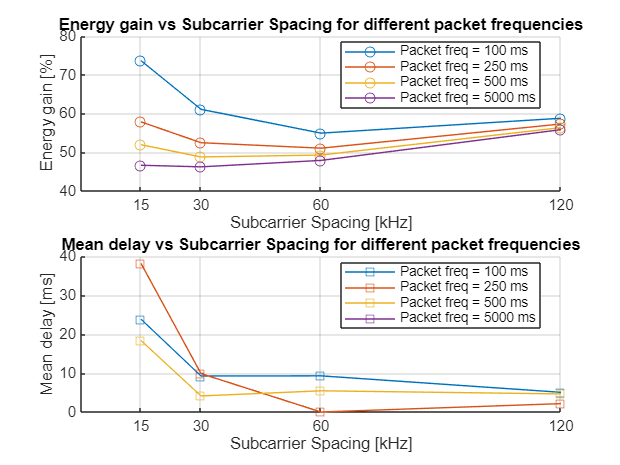


% Rysowanie wykresów
figure;

% Wykres Energy Gain vs SCS
subplot(2, 1, 1);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(scs, energy_gains_1(:, freq_idx), '-o', ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy gain vs Subcarrier Spacing for different packet frequencies');
xlabel('Subcarrier Spacing [kHz]');
ylabel('Energy gain [%]');
legend('Location', 'best');
grid on;
xticks(scs); % Ustawienie dokładnych wartości SCS na osi X

% Wykres Mean Delay vs SCS
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(scs, mean_delays_1(:, freq_idx), '-s', ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean delay vs Subcarrier Spacing for different packet frequencies');
xlabel('Subcarrier Spacing [kHz]');
ylabel('Mean delay [ms]');
legend('Location', 'best');
grid on;
xticks(scs); % Ustawienie dokładnych wartości SCS na osi X



% dla scs 15kHz dla packet frequency 100 - energy gain jest tak wysokie
% ponieważ najwięcej energii zuzywa urządzenie gdy pobiera energie - dla
% 15kHz pobiera ją 2 razy dłużej niż dla 30kHz np i dlategpo tak dużo

% Wykres 2: zmienny SSSG1_frequency
% Parametry stałe
T_total = 3000;
scs = 30;
SSSG0_frequency = 1;
SSSG1_frequency = [2, 4, 5, 8, 10, 16, 20, 40, 80, 160]; % Badane wartości
P_switch = 25;
searchSpaceSwitchTimer = 80;
packet_frequency = [250, 500, 750, 1000, 5000];
packet_data_duration = 20;
dci_latency = 6;

% Inicjalizacja wyników
energy_gains_2 = zeros(length(SSSG1_frequency), length(packet_frequency));
mean_delays_2 = zeros(length(SSSG1_frequency), length(packet_frequency));

% Symulacja dla każdej SSSG1_frequency i każdej częstotliwości pakietów
for freq_idx_sssg = 1:length(SSSG1_frequency)
    
    for freq_idx_pkt = 1:length(packet_frequency)
        [energy_gains_2(freq_idx_sssg, freq_idx_pkt), mean_delays_2(freq_idx_sssg, freq_idx_pkt)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs, SSSG0_frequency, SSSG1_frequency(freq_idx_sssg), ...
                P_switch, searchSpaceSwitchTimer, packet_frequency(freq_idx_pkt), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 3000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 2 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 250 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 70.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energy

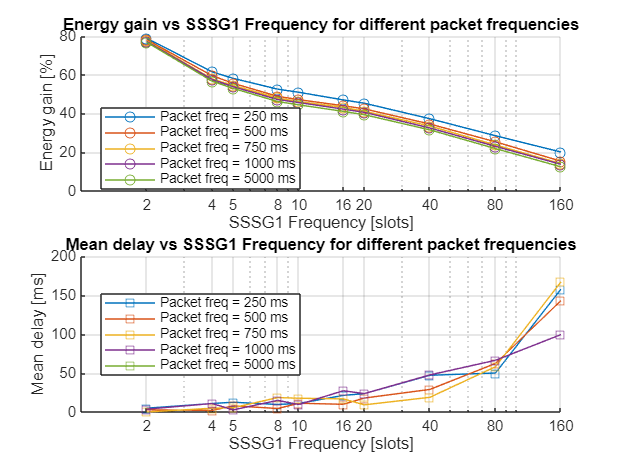


% Rysowanie wykresów
figure;

% Wykres Energy Gain vs SSSG1_frequency
subplot(2, 1, 1);
hold on;
colors = lines(length(packet_frequency));
for freq_idx = 1:length(packet_frequency)
    semilogx(SSSG1_frequency, energy_gains_2(:, freq_idx), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy gain vs SSSG1 Frequency for different packet frequencies');
xlabel('SSSG1 Frequency [slots]');
ylabel('Energy gain [%]');
legend('Location', 'best');
grid on;
xticks(SSSG1_frequency); % Ustawienie dokładnych wartości na osi X
set(gca, 'XScale', 'log'); % Skala logarytmiczna dla lepszej czytelności

% Wykres Mean Delay vs SSSG1_frequency
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequency)
    semilogx(SSSG1_frequency, mean_delays_2(:, freq_idx), '-s', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean delay vs SSSG1 Frequency for different packet frequencies');
xlabel('SSSG1 Frequency [slots]');
ylabel('Mean delay [ms]');
legend('Location', 'best');
grid on;
xticks(SSSG1_frequency); % Ustawienie dokładnych wartości na osi X
set(gca, 'XScale', 'log'); % Skala logarytmiczna dla lepszej czytelności


% bez sensu żeby SSSG1_frequency była większa niż packet_frequency

% Wykres 3: różne SSSGSwitch Timers
% Parametry stałe
T_total = 1000;
SSSG0_frequency = 1;
SSSG1_frequency = 8;
P_switch = 25;
packet_frequency = [100, 250, 500];
packet_data_duration = 20;
dci_latency = 6;

%% SCS 15 kHz - Konfiguracja i obliczenia
scs_15 = 15;
valid_timers_15 = [10, 20, 30, 40, 50, 60, 70, 80, 90, 100, 120, 150];

energy_gains_15 = zeros(length(valid_timers_15), length(packet_frequency));
mean_delays_15 = zeros(length(valid_timers_15), length(packet_frequency));

for timer_idx = 1:length(valid_timers_15)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_15(timer_idx, freq_idx), mean_delays_15(timer_idx, freq_idx)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs_15, SSSG0_frequency, SSSG1_frequency, ...
                P_switch, valid_timers_15(timer_idx), packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 1000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 10 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 250.64
Time 0.00 ms | SSSG0 monitoring | Counter: 5 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 4 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 3 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no switch)
Time 3.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 400.00 mJ (switching) / 400.00 mJ (no switch)
Time 4.00 ms | SSSG0 monitoring | Counter: 1 | Energy used: 500.00 mJ (switching) / 500.00 mJ (no switch)
Time 5.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 600.00 mJ (switching) / 600.00 mJ (no switch)
Time 6.00 ms | SSSG0 monitor

%% SCS 30 kHz - Konfiguracja i obliczenia
scs_30 = 30;
valid_timers_30 = [20, 40, 60, 80, 100, 120, 140, 160, 180, 200, 250];

energy_gains_30 = zeros(length(valid_timers_30), length(packet_frequency));
mean_delays_30 = zeros(length(valid_timers_30), length(packet_frequency));

for timer_idx = 1:length(valid_timers_30)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_30(timer_idx, freq_idx), mean_delays_30(timer_idx, freq_idx)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs_30, SSSG0_frequency, SSSG1_frequency, ...
                P_switch, valid_timers_30(timer_idx), packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 1000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 20 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energ

%% SCS 60 kHz - Konfiguracja i obliczenia
scs_60 = 60;
valid_timers_60 = [40, 80, 120, 160, 200, 240, 280, 320, 360, 400, 500];

energy_gains_60 = zeros(length(valid_timers_60), length(packet_frequency));
mean_delays_60 = zeros(length(valid_timers_60), length(packet_frequency));

for timer_idx = 1:length(valid_timers_60)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_60(timer_idx, freq_idx), mean_delays_60(timer_idx, freq_idx)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs_60, SSSG0_frequency, SSSG1_frequency, ...
                P_switch, valid_timers_60(timer_idx), packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 1000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 40 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 70.64
Time 0.00 ms | SSSG0 monitoring | Counter: 1 | Energy used: 25.00 mJ (switching) / 25.00 mJ (no switch)
Time 0.25 ms | SSSG0 monitoring | Counter: 0 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 0.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 75.00 mJ (switching) / 75.00 mJ (no switch)
Time 0.75 ms | SSSG0 monitoring | Counter: 23 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 22 | Energy used: 125.00 mJ (switching) / 125.00 mJ (no switch)
Time 1.25 ms | SSSG0 monitoring | Counter: 21 | Energy us

%% SCS 120 kHz - Konfiguracja i obliczenia
scs_120 = 120;
valid_timers_120 = [40, 80, 160, 200, 320, 480, 640];

energy_gains_120 = zeros(length(valid_timers_120), length(packet_frequency));
mean_delays_120 = zeros(length(valid_timers_120), length(packet_frequency));

for timer_idx = 1:length(valid_timers_120)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_120(timer_idx, freq_idx), mean_delays_120(timer_idx, freq_idx)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs_120, SSSG0_frequency, SSSG1_frequency, ...
                P_switch, valid_timers_120(timer_idx), packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 1000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 40 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 40.64
Time 0.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 12.50 mJ (switching) / 12.50 mJ (no switch)
Time 0.12 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 0.12 ms | SSSG0 monitoring | Counter: 24 | Energy used: 25.00 mJ (switching) / 25.00 mJ (no switch)
Time 0.25 ms | SSSG0 monitoring | Counter: 23 | Energy used: 37.50 mJ (switching) / 37.50 mJ (no switch)
Time 0.38 ms | SSSG0 monitoring | Counter: 22 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 21 | Energy used: 62.50 mJ (switching) / 62.50 mJ (no switch)
Time 0.62 ms | SSSG0 monitoring | Counter: 20 | Energy used:

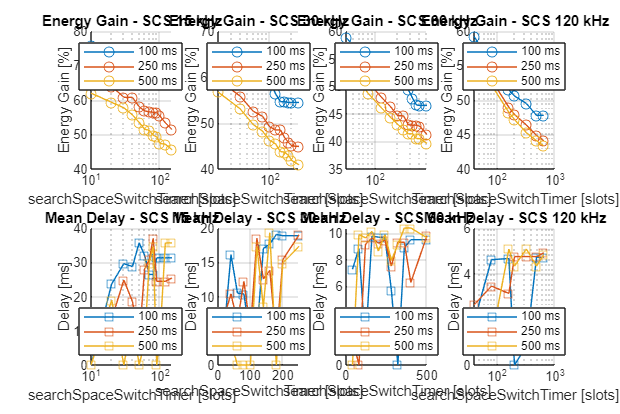

%% Rysowanie wykresów
figure('Position', [100 100 1200 800]);

% Kolory dla różnych częstotliwości pakietów
colors = lines(length(packet_frequency));

% Wykresy Energy Gain - górny rząd
subplot(2,4,1);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_15, energy_gains_15(:, freq_idx), '-o', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy Gain - SCS 15 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Energy Gain [%]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');

subplot(2,4,2);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_30, energy_gains_30(:, freq_idx), '-o', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy Gain - SCS 30 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Energy Gain [%]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');

subplot(2,4,3);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_60, energy_gains_60(:, freq_idx), '-o', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy Gain - SCS 60 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Energy Gain [%]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');

subplot(2,4,4);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_120, energy_gains_120(:, freq_idx), '-o', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy Gain - SCS 120 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Energy Gain [%]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');

% Wykresy Mean Delay - dolny rząd
subplot(2,4,5);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_15, mean_delays_15(:, freq_idx), '-s', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean Delay - SCS 15 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Delay [ms]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');

subplot(2,4,6);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_30, mean_delays_30(:, freq_idx), '-s', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean Delay - SCS 30 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Delay [ms]');
legend('Location', 'best');
grid on;

subplot(2,4,7);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_60, mean_delays_60(:, freq_idx), '-s', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean Delay - SCS 60 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Delay [ms]');
legend('Location', 'best');
grid on;

subplot(2,4,8);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(valid_timers_120, mean_delays_120(:, freq_idx), '-s', ...
        'Color', colors(freq_idx,:), ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean Delay - SCS 120 kHz');
xlabel('searchSpaceSwitchTimer [slots]');
ylabel('Delay [ms]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');

% Wykres 4: zmienny dci_latency
% Parametry stałe
T_total = 2500;
scs = 30;
SSSG0_frequency = 1;
SSSG1_frequency = 8; % Stała wartość
P_switch = 25;
searchSpaceSwitchTimer = 80;
packet_frequency = [100, 250, 500, 5000];
packet_data_duration = 20;
dci_latency_values = [1, 2, 3, 4, 6, 8, 10, 12, 15, 20]; % Badane wartości

% Inicjalizacja wyników
energy_gains_3 = zeros(length(dci_latency_values), length(packet_frequency));
mean_delays_3 = zeros(length(dci_latency_values), length(packet_frequency));

% Symulacja dla każdej dci_latency i każdej częstotliwości pakietów
for dci_idx = 1:length(dci_latency_values)
    current_dci_latency = dci_latency_values(dci_idx);
    
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_3(dci_idx, freq_idx), mean_delays_3(dci_idx, freq_idx)] = ...
            sssg_switching_with_timer_script(...
                T_total, scs, SSSG0_frequency, SSSG1_frequency, ...
                P_switch, searchSpaceSwitchTimer, packet_frequency(freq_idx), ...
                packet_data_duration, current_dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 2500 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 1 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 0.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 21 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 20 | Ene

Energy gains:


   59.1441   51.9574   48.1117   45.6110
   59.1441   51.9574   48.1117   45.6110
   60.3324   52.0579   48.8425   45.7404
   60.3324   52.0579   48.8425   45.7404
   61.0814   52.4600   48.7877   46.2357
   60.4161   52.5605   49.1105   46.7094
   61.8813   52.9625   49.4331   47.2054
   62.3203   53.0630   49.7362   47.2582
   63.0680   53.5742   50.6173   48.2062
   67.5503   55.1067   51.4902   48.7139



Mean delays:


   11.9083    9.8472    8.4000       NaN
   11.9083    9.8472    8.4000       NaN
   10.5625   10.5139         0       NaN
   10.5625   10.5139         0       NaN
    9.2302    9.8472    4.1188       NaN
   11.9156   10.5139    6.5625       NaN
    8.3969    9.8472    8.7875       NaN
    8.3833   10.5139   13.7438       NaN
    8.5500   11.7889   15.9500       NaN
    1.1313    8.2722   17.2312       NaN



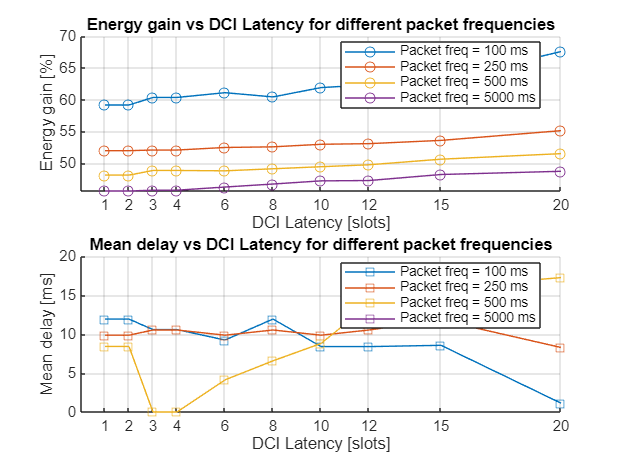


% Rysowanie wykresów
figure;

% Wykres Energy Gain vs dci_latency
subplot(2, 1, 1);
hold on;
colors = lines(length(packet_frequency));
for freq_idx = 1:length(packet_frequency)
    plot(dci_latency_values, energy_gains_3(:, freq_idx), '-o', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequency(freq_idx)));
end
hold off;
title('Energy gain vs DCI Latency for different packet frequencies');
xlabel('DCI Latency [slots]');
ylabel('Energy gain [%]');
legend('Location', 'best');
grid on;
xticks(dci_latency_values); % Ustawienie dokładnych wartości na osi X

% Wykres Mean Delay vs dci_latency
subplot(2, 1, 2);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(dci_latency_values, mean_delays_3(:, freq_idx), '-s', ...
        'Color', colors(freq_idx, :), ...
        'DisplayName', sprintf('Packet freq = %d ms', packet_frequency(freq_idx)));
end
hold off;
title('Mean delay vs DCI Latency for different packet frequencies');
xlabel('DCI Latency [slots]');
ylabel('Mean delay [ms]');
legend('Location', 'best');
grid on;
xticks(dci_latency_values); % Ustawienie dokładnych wartości na osi X

%%Porównanie
% Wspólne parametry symulacji
T_total = 5000;                  % Total simulation time (ms)
scs = 30;                         % Subcarrier spacing (kHz)
SSSG0_frequency = 1;              % Monitoring frequency for SSSG0 (slots)
SSSG1_frequency = 8;              % Monitoring frequency for SSSG1 (slots)
P_switch = 25;                    % P_switch value (slots)
searchSpaceSwitchTimer = 80;       % Search space switch timer (slots)
packet_data_duration = 20;        % Time to receive a packet (ms)
dci_latency = 6;                  % DCI latency (slots)
packet_frequencies = [100, 200, 300, 500, 1000]; % Packet frequencies (ms)

% Inicjalizacja wyników
num_freqs = length(packet_frequencies);
energy_results = zeros(2, num_freqs); % 2 tryby SSSG
delay_results = zeros(2, num_freqs);

% Przeprowadzenie symulacji dla każdej częstotliwości pakietów
for i = 1:num_freqs
    freq = packet_frequencies(i);
    
    % 1. SSSG with timer
    [energy_results(1,i), delay_results(1,i)] = sssg_switching_with_timer_script(...
        T_total, scs, SSSG0_frequency, SSSG1_frequency, P_switch, ...
        searchSpaceSwitchTimer, freq, packet_data_duration, dci_latency);
    
    % 2. SSSG with trigger
    [energy_results(2,i), delay_results(2,i)] = sssg_switching_with_trigger_script(...
        T_total, scs, SSSG0_frequency, SSSG1_frequency, P_switch, ...
        freq, packet_data_duration, dci_latency);
end


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energ


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 200 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energ


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 200 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 300 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energ


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 300 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 500 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energ


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 500 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
searchSpaceSwitchTimer value in slots: 80 
Packet frequency: 1000 ms
Buffor in ms indicating when DCI 2_0 is send: 6 ms
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Ener


=== Starting DRX Simulation ===
Total simulation time: 5000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 1000 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 300.00 mJ (switching) / 300.00 mJ (n

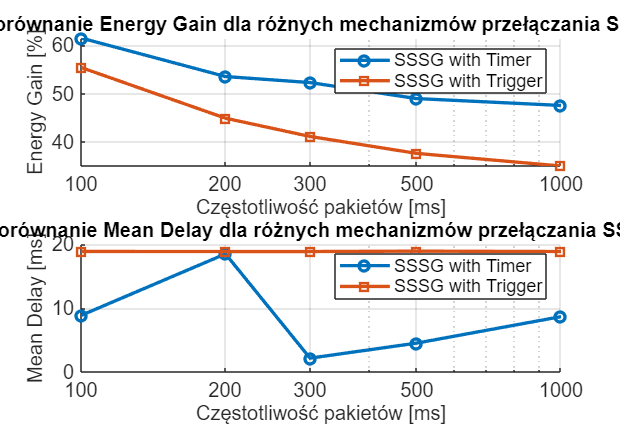


% Wykresy porównawcze
figure('Position', [100 100 1000 700]);

% Wykres Energy Gain
subplot(2,1,1);
hold on;
plot(packet_frequencies, energy_results(1,:), '-o', 'LineWidth', 2, 'DisplayName', 'SSSG with Timer');
plot(packet_frequencies, energy_results(2,:), '-s', 'LineWidth', 2, 'DisplayName', 'SSSG with Trigger');
hold off;
title('Porównanie Energy Gain dla różnych mechanizmów przełączania SSSG');
xlabel('Częstotliwość pakietów [ms]');
ylabel('Energy Gain [%]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');
xticks(packet_frequencies);
xticklabels(arrayfun(@num2str, packet_frequencies, 'UniformOutput', false));

% Wykres Mean Delay
subplot(2,1,2);
hold on;
plot(packet_frequencies, delay_results(1,:), '-o', 'LineWidth', 2, 'DisplayName', 'SSSG with Timer');
plot(packet_frequencies, delay_results(2,:), '-s', 'LineWidth', 2, 'DisplayName', 'SSSG with Trigger');
hold off;
title('Porównanie Mean Delay dla różnych mechanizmów przełączania SSSG');
xlabel('Częstotliwość pakietów [ms]');
ylabel('Mean Delay [ms]');
legend('Location', 'best');
grid on;
set(gca, 'XScale', 'log');
xticks(packet_frequencies);
xticklabels(arrayfun(@num2str, packet_frequencies, 'UniformOutput', false));

% Dodatkowe ulepszenia wizualne
set(findall(gcf, 'Type', 'axes'), 'FontSize', 12);
set(findall(gcf, 'Type', 'text'), 'FontSize', 12);